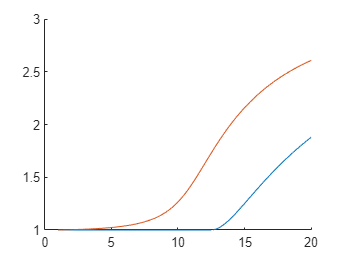


clear all
h = 2e-3;
z = h+eps ;
er = 10 ;
freq = 20.*1e9 ;
freqn = linspace(1e9,20e9,1001);
lambdan=3e8./freqn ;
lambda = 3e8./freq ;
k0 = 2*pi./lambda ;
ky = 0 ;
zeta0 = 120*pi ;
no_ofpt = 1001 ;

lst= k0.*sqrt(er) ;
krho = linspace(eps,lst,no_ofpt) ;
krho_norm = linspace(1,sqrt(er),no_ofpt) ;

% figure
% plot(krho./k0,abs(D))
% figure
% plot(krho./k0,abs(Dn))
% plot(freqn,abs(krholoop))
for ii = length(freqn):-1:1
    k0 = 2.*pi.* freqn(ii)./3e8 ;
    krho = krho_norm .* k0 ;
    [krhonte(ii),krho_newte(ii)] = IterativeMethod(h,er,freqn(ii),'GroundSlab','TE',krho) ;
    [krhontm(ii),krho_newtm(ii)] = IterativeMethod(h,er,freqn(ii),'GroundSlab','TM',krho) ;
end
figure
hold on
plot(freqn./1e9,abs(krhonte))
plot(freqn./1e9,abs(krhontm))
ylim([1 3]);

## Question 2: 

Write a Matlab routine to calculate the field contribution, in cylindrical coordinates,  associated to the TM0 surface wave excited by a half-wavelength dipole (l=15 mm, w=0.5 mm) on top of a grounded slab. Provide the following plots (h=2 mm, εr=10, f=10 GHz):

• Real and imaginary part variation of the electric field as a function of the radial  distance. Finished(Need to create better plots)

• Amplitude variation of the electric field components as a function of z. 

• Amplitude variation of the electric field as a function of φ. Finished(Need to create better plots)

clear 
l = 15e-3 ;
w = 0.5e-3 ;
h = 2e-3 ;
er = 10; 
f= 10e9 ;
k0 = 2.*pi.* f./3e8 ;
no_ofpt = 1001 ;
phi = linspace(eps,2*pi,303) ;
lambdas = 3e8./(f.*sqrt(er)) ;
rho = linspace(eps,15 .*lambdas,101) ;% linspace(eps,1,200) ;
[RHO,PHI] = meshgrid(rho,phi) ;
z = linspace(eps,h+23e-3,303) ;

lst= k0.*sqrt(er) ;
krho = linspace(eps,lst,no_ofpt) ;
% Erhotm=zeros(size(RHO))
for ii = 1:length(z)
    [~,kswTM] = IterativeMethod(h,er,f,'GroundSlab','TM',krho) ;
    [VrTM,IrTM] = Residue_GroundSlab(k0,er,h,kswTM,z(ii),f,'TM') ;
    [Erhotm(:,:,ii),Ephitm(:,:,ii),Eztm(:,:,ii)] = SwFields(k0,kswTM,er,VrTM,IrTM,RHO,PHI,l,w) ;
    EtotTM(:,:,ii) = sqrt( abs(Erhotm(:,:,ii)).^2 + abs(Ephitm(:,:,ii)).^2 + abs(Eztm(:,:,ii)).^2 ) ;

    [~,kswTE] = IterativeMethod(h,er,f,'GroundSlab','TE',krho) ;
    [VrTE,IrTE] = Residue_GroundSlab(k0,er,h,kswTE,z(ii),f,'TE') ;
    [Erhote(:,:,ii),Ephite(:,:,ii),Ezte(:,:,ii)] = SwFields(k0,kswTE,er,VrTE,IrTE,RHO,PHI,l,w) ;
    EtotTE(:,:,ii) = sqrt( abs(Erhote(:,:,ii)).^2 + abs(Ephite(:,:,ii)).^2 + abs(Ezte(:,:,ii)).^2 ) ;
end
% [~,~,ResTM,~] = residue_stratified(k0, kswTE, kswTM, z, 'GroundSlab',h,er)

figure 
hold on
plot(rad2deg(phi),(EtotTM(:,length(rho),13)),'DisplayName','TM') ;
% plot(rad2deg(phi),(EtotTM(:,:,13)),'DisplayName','TE') ;
hold off
legend('Location','best','Interpreter','latex')
xlabel('$\phi[deg]$', 'Interpreter','latex');
ylabel('$\left|E\right|$', 'Interpreter','latex');
xlim([0 360]) ;


figure
plot((rho)./lambdas,(real(Erhotm(1,:,13))),'DisplayName','real') ;
hold on
plot((rho)./lambdas,(imag(Erhotm(1,:,13))),'DisplayName','imag') ;
legend
title('Cagins oscillations at z=1mm')
ylim([-3e4 3e4])


figure
plot(z./1e-3,squeeze(EtotTM(1,length(rho),:)),'DisplayName','z') ;
legend

## Question 3: 

Write a Matlab routine to calculate the power radiated into the TM0 surface wave of a dipole antenna printed on top of a grounded slab. Provide the following plots (ℎ = 2 mm, 𝜀𝑟 = 10, 𝑓 = 1 − 15 GHz):

 -> The far field power and surface wave power radiated by an elementary dipole (𝐽 = 1) normalized to the power radiated by the same dipole in free space.

-> The TM0 surface wave efficiency for the elementary dipole and for a dipole with 𝑙 = 5.3 mm and 𝑤 = 0.5 mm (assume a PWS distribution). 

-> The TM0 surface efficiency for a uniform current distribution in both 𝑥 and 𝑦 directions with a dimension of 𝑙 = 𝑤 = 25 mm